## 二群間有意統計プログラム

ver 1.00 21/10/6 桐原

[参考URL](http://www.gen-info.osaka-u.ac.jp/testdocs/tomocom/tebiki.html)

サンプル数2以上の時は使わないで下さい．

多群間比較はまた別です．

**Statistics and Machine Learning Toolbox **が必要

clearvars
close all
data_count=0;
data1=0;
data2=0;
data=table(data_count, data1, data2);
clearvars data_count data1 data2
%一行目にデータ数，二行目にデータ１　三行目にデータ2を入れる．

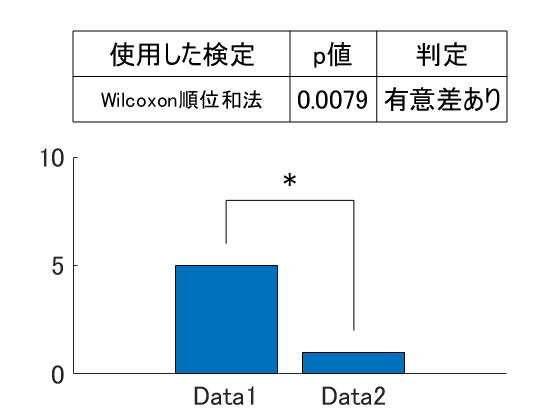

close all
n=zeros(1,8);
sw=true;
name='';
answer = questdlg('データ間に対応はある?', ...
	'手法の選択');
switch answer
    case 'Yes'
        n(1)=2;
    case 'No'
        n(1)=1;
    otherwise
        return
end

answer = questdlg('データは間隔尺度以上?', ...
	'手法の選択');
switch answer
    case 'Yes'
        n(2)=2;
    case 'No'
        n(2)=1;
    otherwise
        return
end

[name,sw]=judge(n,data);


%明らかに正規分布ではないか(Q3)
if(sw)
    n=@test1;
    [name,sw]=judge(n,data);
end

%データ数のカウント(Q4 Q5)
if(sw)
   n=@countdata; 
   [name,sw]=judge(n,data);
end

if(sw)
    fig1=figure();
    hold on
    histogram(data.data1)
    histogram(data.data2)
    %Q6
    answer = questdlg('分布の端で測定値が途切れている，又は明らかな外れ値がある？', ...
    	'手法の選択');
    switch answer
        case 'Yes'
            n(6)=2;
        case 'No'
            n(6)=1;
        otherwise
            return
    end
    [name,sw]=judge(n,data);
end

if(sw)
   n=ftest(n,data); 
   [name,sw]=judge(n,data);
end

if(sw)
    n=question(n);
    [name,sw]=judge(n,data);
end



function n=test1(n,data)
    h1=lillietest(data.data1);
    h2=lillietest(data.data2);
    if h1>0 && h2>0
        n(3)=2;
    else
        n(3)=1;
    end
end

function n=countdata(n,data)
    if data.data_count(1)>99 && data.data_count(2)>99
        n(4)=2;
        if n(1)==1
            n=question(n);%等分散の質問へ
        end
    elseif data.data_count(1)<11 && data.data_count(2)<11
        n(5)=2;
    else
        n(5)=1;
    end
end

function n=ftest(n,data)
    h=vartest2(data.data1,data.data2);
    if(h==1)
        n(7)=2;
    else
        n(7)=1;
    end
end

function n=question(n)
    answer = questdlg('等分散である，もしくは等分散が仮定できる？', ...
    	'手法の選択');
    switch answer
        case 'Yes'
            n(8)=2;
        case 'No'
            n(8)=1;
        otherwise
            return
    end
end

function [name,sw]=judge(n,data)
    a=0;
    for i=1:8
        a=a+n(i)*10^(8-i);
    end
    sw=false;
    if a==11000000||a==21000000
        name={'Wilcoxon順位和法'};
        [p,h]=ranksum(data.data1,data.data2);
    elseif a==1212001||a==12111111
        name={'Welchのt検定'};
        [h,p]=ttest2(data.data1,data.data2);
    elseif a==12200000||a==12112000||a==12111200||a==12111120
        name={'Mann–WhitneyのU検定'};
        [p,h]=ranksum(data.data1,data.data2);
    elseif a==22200000||a==22112000||a==22111200||a==22111120
        name={'Wilcoxon符号付順位和'};
        [p,h]=signrank(data.data1,data.data2);
    elseif a==22120000||a==22111110
        name={'対応のあるt検定'};
        [h,p] = ttest(data.data1,data.data2);
    elseif a==1212002||a==12111112
        name={'Studentのt検定'};
        [h,p] = ttest2(data.data1,data.data2);
    else
        sw=true;
        name='';
    end
    if sw==false
        result(name,p,h,data);
    end
end

function result(name,p,h,data)
    p=round(p,4);
    if h
        hantei='有意差あり';
    else
        hantei='有意差なし';
    end
    fig=figure();
    subplot(3,1,1);
    hold on
    text(1.5,-0.5,name,"VerticalAlignment","middle","HorizontalAlignment","center","FontSize",16);
    text(2.2,-0.5,num2str(p),"VerticalAlignment","middle","HorizontalAlignment","center","FontSize",20);
    text(2.7,-0.5,hantei,"VerticalAlignment","middle","HorizontalAlignment","center","FontSize",20);
    text(1.5,0.5,"使用した検定","VerticalAlignment","middle","HorizontalAlignment","center","FontSize",20);
    text(2.2,0.5,"p値","VerticalAlignment","middle","HorizontalAlignment","center","FontSize",20);
    text(2.7,0.5,"判定","VerticalAlignment","middle","HorizontalAlignment","center","FontSize",20);
    line([1,1],[-1,1],'Color','k');
    line([3,3],[-1,1],'Color','k');
    line([1,3],[1,1],'Color','k');
    line([1,3],[-1,-1],'Color','k');
    line([1,3],[0,0],'Color','k');
    line([2,2],[-1,1],'Color','k');
    line([2.4,2.4],[-1,1],'Color','k');
    ax = gca;
    ax.XAxis.Visible = 'off';
    ax.YAxis.Visible = 'off';
    xlim([1,3])
    hold off
    subplot(3,1,[2,3]);
    hold on
    x=[mean(data.data1(1:data.data_count(1))),mean(data.data2(1:data.data_count(2)))];
    bar(x);
    se=[var(data.data1(1:data.data_count(1)))/sqrt(data.data_count(1)),var(data.data2(1:data.data_count(2)))/sqrt(data.data_count(2))];
    er = errorbar([1,2],x,se,se);%errorbar([x範囲],[y範囲],[下限],[上限])
    er.Color = [0 0 0];%errorbarの色
    er.LineStyle = 'none';%errorbarの線
    
    set(gca,'FontSize',20);
    if h
        if sign(max(x))>0
            ylim([min(0,2*round(max(x+se),1)),max(0,2*round(max(x+se),1))])
            %有意差
            dis=max(x)/5;
            up=max(x+se)+dis*3;
            x_point=[1,2];
            y_point=x+se;
            %以上が変数
            
            line([x_point(1),x_point(1)],[y_point(1)+dis,up],'Color','k');
            line([x_point(2),x_point(2)],[y_point(2)+dis,up],'Color','k');
            line([x_point(1),x_point(2)],[up,up],'Color','k');
            if p<0.001
                a='***';
            elseif p<0.005
                a='**';
            else
                a='*';
            end 
                text(mean(x_point),up+dis,a,'Color','k','FontSize',20,"HorizontalAlignment","center")
        else
            ylim([min(0,2*round(min(x-se),1)),max(0,2*round(min(x-se),1))])
            %有意差
            dis=min(x)/5;
            up=min(x-se)+dis*3;
            x_point=[1,2];
            y_point=x-se;
            %以上が変数
            
            line([x_point(1),x_point(1)],[y_point(1)+dis,up],'Color','k');
            line([x_point(2),x_point(2)],[y_point(2)+dis,up],'Color','k');
            line([x_point(1),x_point(2)],[up,up],'Color','k');
            if p<0.001
                a='***';
            elseif p<0.005
                a='**';
            else
                a='*';
            end 
                text(mean(x_point),up+dis,a,'Color','k','FontSize',20,"HorizontalAlignment","center")
        end
        
    else
        if sign(max(x))>0
            ylim([min(0,1.1*round(max(x+se),1)),max(0,1.1*round(max(x+se),1))])
        else
            ylim([min(0,1.1*round(min(x-se),1)),max(0,1.1*round(min(x-se),1))])
        end
        %ylim([0 round(max(mean(x+se),1))])
    end
    xticks([1 2]);
    xticklabels({'Data1', 'Data2'});
    hold off
    saveas(fig,'result.png');
end